#  ECSE 343: Numerical Methods in Engineering

#  Assignment 3

Due Date: 29th nov 2021

Student Name:Lawi Mwirigi

Student ID:    260831614

Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

Please submit this **.mlx** file along with a **PDF** copy of this file.

Note: You can write the function in the appendix section using the provided stencils.

**In this assignment you may use the backslash operator, '\' to solve systems such as Ax=b.**

Question 1: **Nonlinear Equations for univariate case.**

a) Bisection Method is used for finding the roots of a continuous function, $f\left(x\right)$, given endpoints;$a,b$ with $f\left(a\right)\ldotp f\left(b\right)<0$ . The interval $\left\lbrack a\;\;b\right\rbrack$contains a root, $x_r$, because $f\left(a\right)$ and $f\left(b\right)$ have opposite signs.

Bisection method bisects the given interval at the midpoint, $c=\frac{a+b}{2}$ and then chooses a new interval based such that end of point of interval have opposite signs, i.e., if $f\left(a\right)\ldotp f\left(c\right)<0$, then the new interval is set to $\left\lbrack a\;\;c\right\rbrack$, else if $f\left(c\right)\ldotp f\left(b\right)<0$ then the interval is set to $\left\lbrack c\;\;b\right\rbrack$.

The above procedure is repeated until the following two conditions are simultaneously met, 

- The function value at the interval is sufficiently small, i.e., ${\left\|f\left(c\right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The new interval is sufficiently small, i.e., ${\left\|a-b\right\|}_2 <\epsilon_{\textrm{tolerance}}$

Implement the Bisection Method in the cell below to find the root of $f\left(x\right)=x^4 -{2\;x}^2 -4$ in the interval $\left\lbrack -3\;\;\;0\right\rbrack \;$using $\epsilon_{\textrm{tolerance}} ={10}^{-5}$. **Show the number of iterations the bisection method took to converge.**

Use the cell below to implement your code. 

Note: There is no need to write the function for Bisection Method. However, if you wish to implement the function, use the appendix.

%implement your bisection method here
f=@(x)x^4-2*x^2-4;
a=-3;
b=0;
tol = 10^-5;

[c,counter]= bisectionMethod(f,a,b,tol)

fc = 1.2621e-06

c = -1.7989

counter = 22

b) ** Newton-Raphson**

 Bisection Method requires the given function,$f\left(x\right)$ to be continuous, Newton-Raphson requires $f\left(x\right)$ to be continuous and differentiable. While the Newton- Raphson method converges faster than the bisection method, however, Newton-Raphson method does not guarantee convergence. Newton-Raphson works by linearising the $f\left(x\right)$, at the given initial guess, $x^{\left(0\right)}$as shown below


$$f\left(x\right)=f\left(x^{\left(0\right)} \right)+{f\left(x^{\left(0\right)} \right)}^{\prime } \left(x-x^{\left(0\right)} \right)$$


Setting the expression on the right to zero, provides an approximation to the root, and we obtain


$$x^{\left(1\right)} =x^{\left(0\right)} -\frac{f\left(x^{\left(0\right)} \right)}{{f\left(x^{\left(0\right)} \right)}^{\prime } }$$


Then, the function,$\;f\left(x\right)$, is again linearised using approximation,$x^{\left(1\right)}$as the initial guess, to obtain new approximation of the root. After $k$ iterations the new approximation for the root becomes,

  
$$x^{\left(k+1\right)} =x^{\left(k\right)} -\frac{f\left(x^{\left(k\right)} \right)}{{f\left(x^{\left(k\right)} \right)}^{\prime } }$$


The above procedure is repeated untill the following two convergence condtions are simultaneously met,  

- The function value at new guess point is sufficiently small, i.e., ${\left\|f\left(x^{\left(k+1\right)} \right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The difference between the two consecutive solutions is sufficiently small, i.e., ${\left\|\Delta x^{\left(k+1\right)} \right\|}_2 <\epsilon_{\textrm{tolerance}}$

where $\Delta x^{\left(k+1\right)} =$$x^{\left(k+1\right)} -x^{\left(k\right)}$.

Implement the **Newton-Raphson** Method in the cell below to find the root of $f\left(x\right)=x^4 -{2\;x}^2 -4$ use intial guess of $x^{\left(0\right)} =-3$ using $\epsilon_{\textrm{tolerance}} ={10}^{-5}$.  If the convergence is not reached in 100 iterations, quit the algorithm by displaying an error message indicating that Newton-Raphson failed to converge. 

Plot the 2-Norm of difference between consecutive solutions ${\left\|x^{\left(k+1\right)} -x^{\left(k\right)} \right\|}_2$  for each iteration. 

% write your code here
f=@(x)x^4-2*x^2-4;
fderivative = @(x)4*x^3-4*x;
x0=-3;
tol = 10^-5;
nmax=100;


[x,deltaX]=newtonraphson(f,fderivative,x0,tol,nmax)

x = -1.7989

deltaX =     0.0521    0.6319    0.3954    0.1836    0.0405    0.0018    0.0000


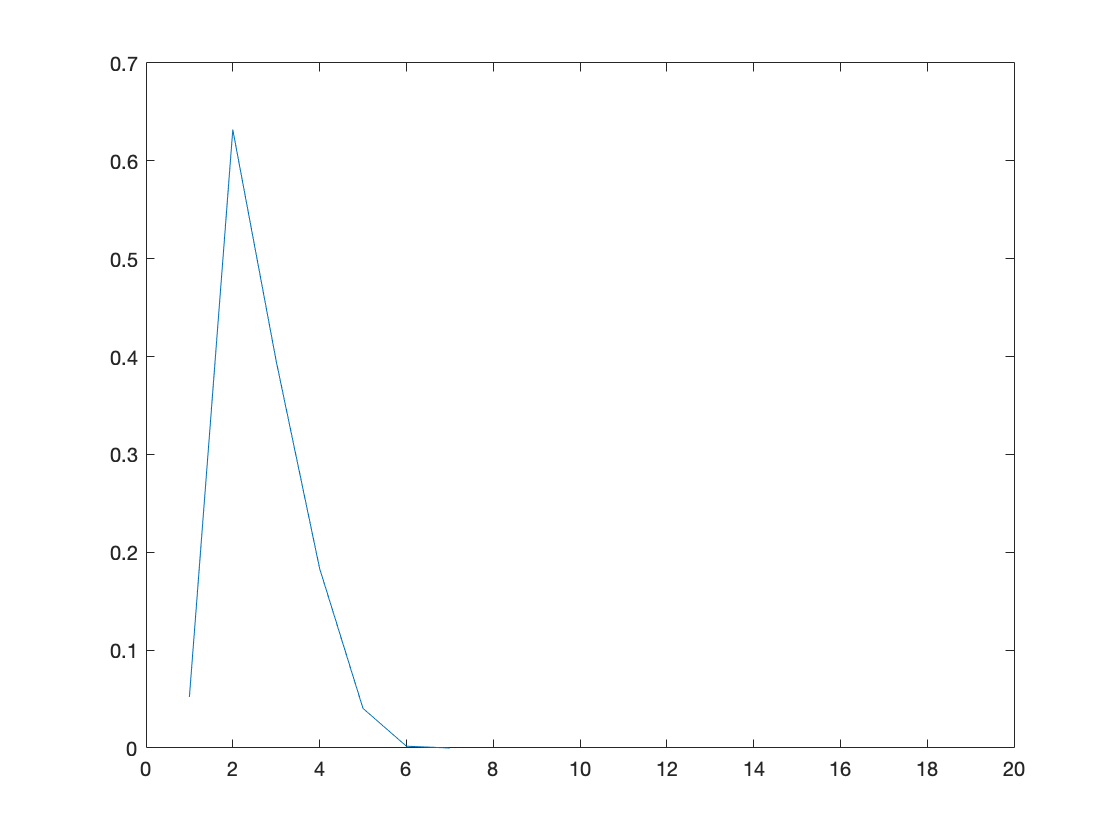

plot(deltaX)
xlim ([0,20]);

Question 2:  **Nonlinear Equations for N-variables.**

 Newton-Raphson Method can be used to solve the system of nonlinear equations of N-variables, $\left\lbrack x_1 ,\;x_2 ,\;\cdots ,\;x_n \right\rbrack$shown below,


$$f_1 \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$



$$f_2 \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$
 


$$\vdots$$



$$f_N \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$


The above equations can be written as a vector valued function as shown below,


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
f_1 \left(x_1 ,x_2 ,\cdots ,x_N \right)\\
f_2 \left(x_1 ,x_2 ,\cdots ,x_N \right)\\
\vdots \\
f_N \left(x_1 ,x_2 ,\cdots ,x_N \right)
\end{array}\right\rbrack$$


where $\mathit{\mathbf{X}}=\left\lbrack x_1 ,x_2 ,\cdots ,x_N \right\rbrack$ is the vector containing all the variables.

Following the idea of unidimensional Newton-Rapshson, we start with an initial guess ${\mathit{\mathbf{X}}}^{\left(0\right)}$ and we use this to linearise the function $\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)$ around${\;\mathit{\mathbf{X}}}^{\left(0\right)}$ 


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\;$$

$$f\left({\mathit{\mathbf{X}}}^{\left(0\right)} \right)+\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(0\right)} \right)\right)\left(\mathit{\mathbf{X}}-{\mathit{\mathbf{X}}}^{\left(0\right)} \right)$$


Setting the expresson on the left side to zero, we find the approximation of the solution vector. After $k$ iteration the approximation for the solution vector can be written as 


$${\mathit{\mathbf{X}}}^{\left(k+1\right)} =$$

$${\mathit{\mathbf{X}}}^{\left(k\right)} -{\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)}^{-1} \mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$$


where $\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$ is the vector valued fucntion evaluated at ${\mathit{\mathbf{X}}}^{\left(k\right)}$ and $\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)$ is the jacobian evaluated at ${\mathit{\mathbf{X}}}^{\left(k\right)}$. The structure of the Jacobian is given by,


$$\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{cccc}
\frac{\partial f_1 }{\partial x_1 } & \frac{\partial f_1 }{\partial x_2 } & \cdots  & \frac{\partial f_1 }{\partial x_n }\\
\frac{\partial f_2 }{\partial x_1 } & \frac{\partial f_2 }{\partial x_2 } & \cdots  & \frac{\partial f_2 }{\partial x_n }\\
\vdots  & \vdots  & \ddots  & \vdots \\
\frac{\partial f_n }{\partial x_1 } & \frac{\partial f_n }{\partial x_2 } & \cdots  & \frac{\partial f_n }{\partial x_n }
\end{array}\right\rbrack$$


The above procedure is repeated untill the following two convergence condtions are simultaneously met,  

- The function value at new guess point is sufficiently small, i.e., ${\left\|\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k+1\right)} \right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The difference between the two consecutive solutions is sufficiently small, i.e., ${\left\|{\mathit{\mathbf{X}}}^{\left(k+1\right)} -{\mathit{\mathbf{X}}}^{\left(k\right)} \right\|}_2 <\epsilon_{\textrm{tolerance}}$

Find a solution of the following system of three nonlinear equations using Newton-Raphson method.


$$x_{1\;}^{2\;} +x_{2\;}^{2\;} +x_3^2 \;=3$$



$$x_{1\;}^{2\;} +\;x_2^2 -x_{3\;} =1$$



$$x_{1\;} +x_{2\;} +x_3 =3$$


Note that this can be expressed as 

$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
x_{1\;}^{2\;} +x_{2\;}^{2\;} +x_3^2 -3\\
x_{1\;}^{2\;} +\;x_2^2 -x_{3\;} -1\\
x_{1\;} +x_{2\;} +x_3 -3
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$,        where $\mathit{\mathbf{X}}={\left\lbrack \begin{array}{ccc}
x_1  & x_2  & x_3 
\end{array}\right\rbrack }^T$

a) Write a MATLAB function named *evaluateEquations(x)*, that evaluates the above equation at a given input vector. Use the provided $\mathit{\mathbf{X}}$ to check your implementation.

Use the framework of the function provided in the Appendix. 

% X in this case is an example
 
X = [2;3;4];

f  = evaluateEquations(X)

f =     26
     8
     6


b) Write a MATLAB function named *evaluateJacobian()*, that evaluates the Jacobian of the above equations. Use the provided $\mathit{\mathbf{X}}$ to check your implementation.

Use the framework of the function provided in the Appendix.  

X = [2;3;4];
J  = evaluateJacobian(X)

J =      4     6     8
     4     6    -1
     1     1     1


**Newton-Raphson **

c) Implement the Newton-Raphson method, use the function named *NewtonRaphson() *to write the code for this. 

Start with intial guess, $X^{\left(0\right)} ={\left\lbrack \begin{array}{ccc}
0 & 0 & 0
\end{array}\right\rbrack }^T$  and then find a suitable intial guess. Plot the 2-Norm of difference between consecutive solutions ${\left\|{\mathit{\mathbf{X}}}^{\left(k+1\right)} -{\mathit{\mathbf{X}}}^{\left(k\right)} \right\|}_2$ for each iteration. 

Use the framework of the function provided in the Appendix.  In the  *NewtonRaphson() *function use the methods implemented in part (a) and (b).

% write your code here
func =@evaluateEquations;
Jac =@evaluateJacobian;
Xguess=[1;2;3]

Xguess =      1
     2
     3


[X,deltaX] = NewtonRaphson(func,Jac,Xguess,1e-5)

X = 	1.0e+-10 *

    0.9025
    0.9025
         0


deltaX =     2.4265    1.2418    0.6226    0.3113    0.1556    0.0778    0.0389    0.0195    0.0097    0.0049    0.0024    0.0012    0.0006    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000


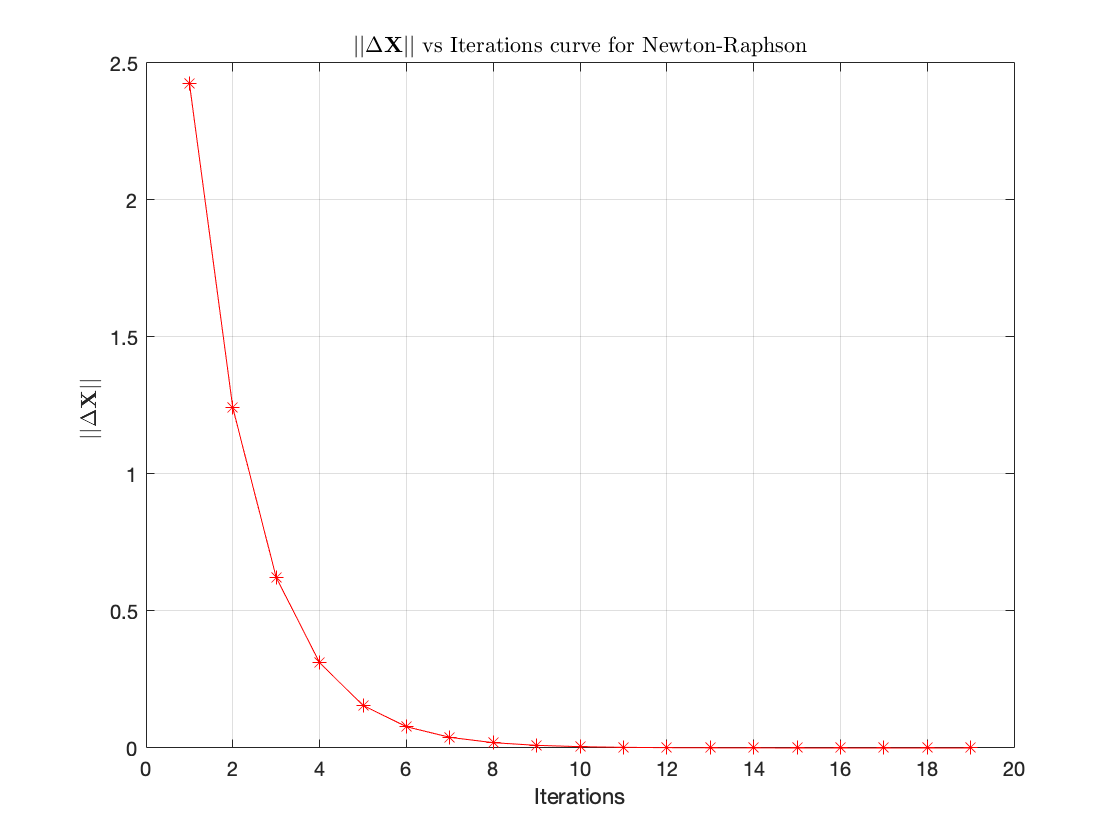




plot(deltaX,'r-*')
xlabel('Iterations')
ylabel(' $ || \Delta \textbf{X} || $ ', 'Interpreter', 'latex')
grid on
title(' $ || \Delta \textbf{X} || $  vs Iterations curve for Newton-Raphson', 'Interpreter', 'latex')

**Newton-Raphson with Broyden's method to approximate Jacobian**

d) Suppose you do not have access to the Jacobian of  the nonlinear eqautions, use the Broyden's method  to compute/ update the Jacobian.  

At the $(k+1)^{th}$ iteration of Newton Raphson, the soltuion vector $\mathit{\mathbf{X}}$  is given by 


$${\mathit{\mathbf{X}}}^{\left(k+1\right)} =$$

$${\mathit{\mathbf{X}}}^{\left(k\right)} -{\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)}^{-1} \mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$$


let, $J_{k\;} =\;\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)$. Using the Broyden's update, $J_{k\;}$ can be computed as 


$$J_{k\;} =J_{k-1} +\;\frac{\;\left(\;\;\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)-\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k-1\right)} \right)\;\;\right)\;-\;\;J_{k-1} \;\;\left({\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \right)\;}{{\left\|\;\;\left({\;\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)} \;\;\right)\;\;\right\|}_2^{2\;} }{\left({\;\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)} \;\right)}^T$$


Write a MATLAB function named* NR_Broyden_Jacobian()*, that evaluates the Jacobian of the above equations. 

Use the initial guess,$X^{\left(0\right)}$ you used in part c). For the intial guess for Jacobian $J_0  =I_{n\times n}$, where $I_{n\times n}$ is the identity matrix and $n$ is the number of equations.

Use the framework of the function provided in the Appendix




func =@evaluateEquations;
[Xout,deltaXBroyden]  = NR_Broyden_Jacobian(func, Xguess,1e-5)

Xout = 	1.0e+-10 *

    0.2448
    0.3375
   -0.0000


deltaXBroyden = 	1.0e+03 *

    0.0114    0.0182    0.0315    0.0517    0.1031    0.1281    0.3179    0.3267    0.1582    0.1714    0.0094    0.0179    0.0073    0.0077    0.0078    0.0074    0.0096    0.0275    0.0384    1.0712    1.0715    0.0009    0.0112    0.0035    0.0006    0.0002    0.0051    0.0043    0.0028    0.0026    0.0099    0.0108    0.0008    0.0157    0.0164    0.0008    0.0033    0.0047    0.0058    0.0012    0.0043    0.0131    0.0145    0.0031    0.0049    0.0010    0.0018    0.0073    0.0079    0.0005


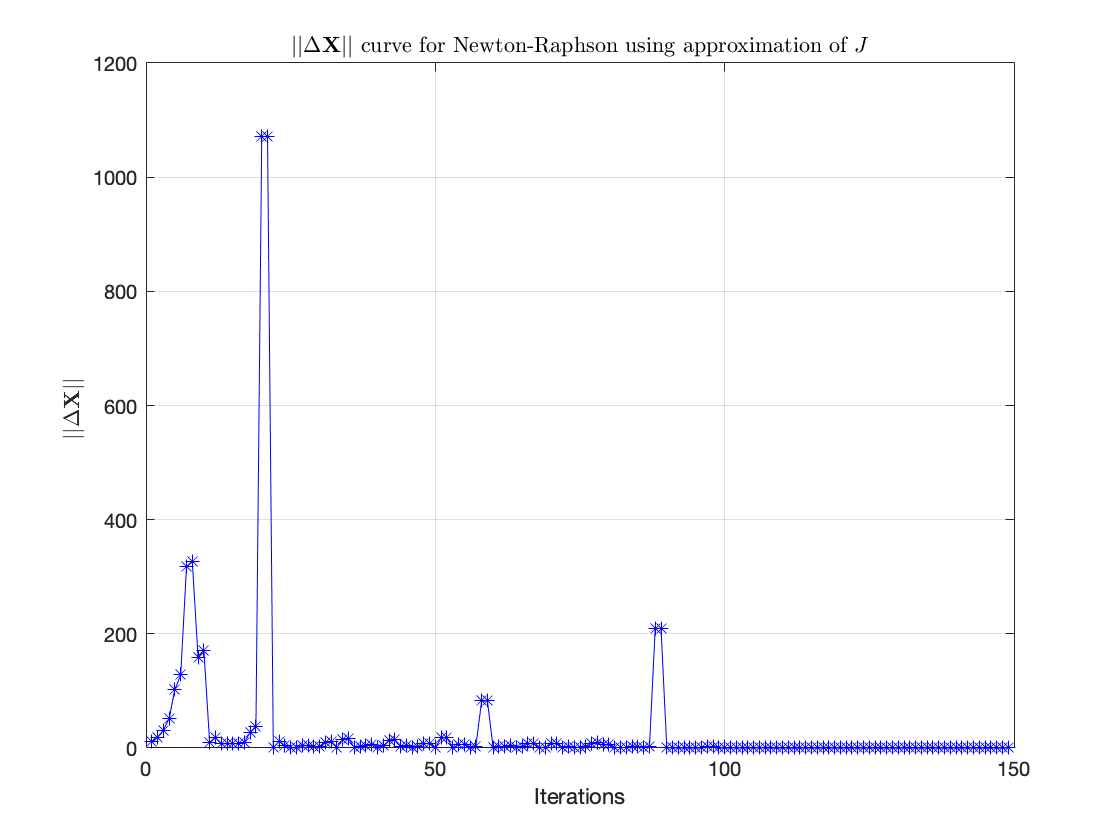

plot(deltaXBroyden,'b-*')
xlabel('Iterations')
ylabel(' $ || \Delta \textbf{X} || $ ', 'Interpreter', 'latex')
grid on
title(' $ || \Delta \textbf{X} || $  curve  for Newton-Raphson using approximation of $J$', 'Interpreter', 'latex')

**Newton-Raphson with Broyden's method to approximate Inverse of Jacobian**

e)  In part d) , you implemented the Broyden's method for updating the Jacobian, in this part use the Broyden's update for computing inverse of Jacobian. The inverse of Jacobian can be computed as 


$$J_{k\;}^{-1} =J_{k-1}^{-1} +\;\frac{\;\left(\;{\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \;\right)-\;J_{k-1}^{-1\;} \;\;\left(\;\;\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)-\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k-1\right)} \right)\;\;\right)\;}{{\left(\;{\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \;\right)}^{T\;} J_{k-1}^{-1} \;\;\left(\;\;\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)-\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k-1\right)} \right)\;\;\right)}\left({\left(\;{\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \;\right)}^{T\;} \;J_{k-1}^{-1} \right)$$


Write a MATLAB function named* NR_Broyden_InvJacobian()*, that evaluates the Jacobian of the above equations. 

Use the initial guess,$X^{\left(0\right)}$ you used in part c). For the intial guess for inverse of Jacobian $J_0^{-1} =I_{n\times n}$, where $I_{n\times n}$ is the identity matrix and $n$ is the number of equations.

Use the framework of the function provided in the Appendix.


func =@evaluateEquations;
[Xout,deltaXBroyden]  = NR_Broyden_InvJacobian(func, Xguess,1e-5)

Xout = 	1.0e+-7 *

    0.9949
    0.6433
    0.0000


deltaXBroyden = 	1.0e+03 *

    0.0114    0.0182    0.0315    0.0517    0.1031    0.1281    0.3179    0.3267    0.1582    0.1714    0.0094    0.0179    0.0073    0.0077    0.0078    0.0074    0.0096    0.0275    0.0384    1.0712    1.0715    0.0009    0.0112    0.0035    0.0006    0.0002    0.0051    0.0043    0.0028    0.0026    0.0099    0.0108    0.0008    0.0157    0.0164    0.0008    0.0033    0.0047    0.0058    0.0012    0.0043    0.0131    0.0145    0.0031    0.0049    0.0010    0.0018    0.0073    0.0079    0.0005


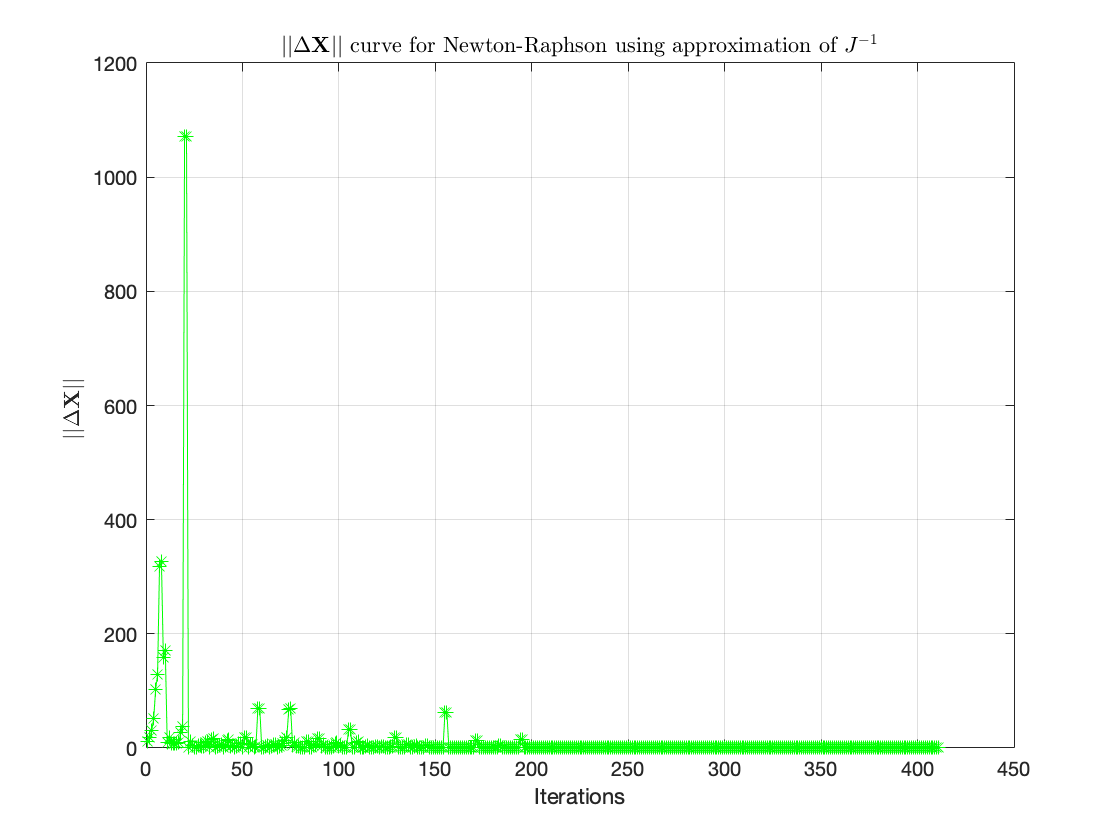

plot(deltaXBroyden,'g-*')
xlabel('Iterations')
ylabel(' $ || \Delta \textbf{X} || $ ', 'Interpreter', 'latex')
grid on
title(' $ || \Delta \textbf{X} || $  curve  for Newton-Raphson using approximation of $J^{-1}$', 'Interpreter', 'latex')

f)  Given a nonlinear system with $n$ number of nonlinear equations, shown below,


$$f_1 \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\;=3x_{1\;} -2x_{1\;}^2 -2x_{2\;} +1=0$$



$$f_i \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\;\;=3x_{i\;} -2{x_i }_{\;}^2 -x_{i-1} -2x_{i+1} +1=0,\;\;\;\;\;\textrm{for}\;\;\;1<i<n$$


 
$$f_n \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)=3x_{n\;} -2{x_n }_{\;}^2 -x_{n-1} +1=0$$


where, $x_1$, $x_2$, ..., $x_n$  are the variables. 

The nonlinear vector of equations can written as, 


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
f_1 \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\\
f_2 \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\\
\vdots \\
f_i \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\\
\vdots \\
f_n \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
0\\
\vdots \\
0
\end{array}\right\rbrack$$


The Matlab function to evalaute the above function is named *nlfunction() *and  it is  provided to you in appendix. 

Suppose you  do not have access to the jacobian, so you chose to solve the above nonlinear function using Broyden's methods you developed in part (d) and (e). The code cell below uses the Broyden's algorithms you implemented in paer d) and  e) to solve the above nonlinear system for different size of the system ranging from  $10\le n\le 200$. 

Run the cell below and explain the results in Figure Question 2 f.

clear all
func1 = @nlfunction;
c = 1

c = 1

N = 200

N = 200

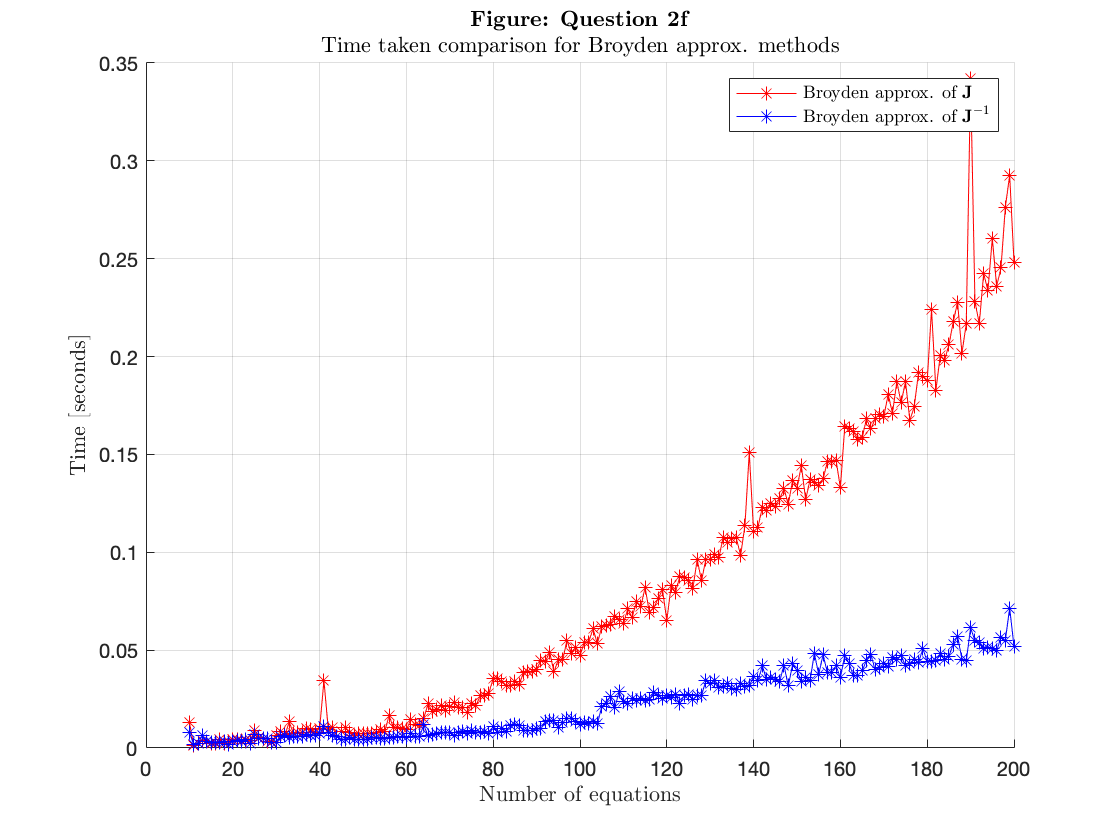

time_BroydenIJ = zeros(N-10+1,1);
time_BroydenJ = zeros(N-10+1,1);
for I=10:N
Xguess = zeros(I,1);
brIJstart =tic ;
[XBrIJ,deltaXBroyden]  = NR_Broyden_InvJacobian(func1,Xguess,1e-6);
time_BroydenIJ(c) = toc(brIJstart) ;

brJstart =tic ;
[XBrJ,deltaXBroyden]  = NR_Broyden_Jacobian(func1,Xguess,1e-6);
time_BroydenJ(c) = toc(brJstart) ;

c =c +1;
end

figure()
clf
hold on 
plot(10:N,time_BroydenJ,'r-*')
plot(10:N,time_BroydenIJ,'b-*')

legend('Broyden approx. of $\textbf{J}$' ,'Broyden approx. of $\textbf{J}^{-1}$','Interpreter','latex')
title({'\textbf{Figure: Question 2f}','Time taken comparison for Broyden approx. methods'}, 'Interpreter', 'latex')
ylabel('Time [seconds]', 'Interpreter', 'latex')
xlabel('Number of equations', 'Interpreter', 'latex')
grid on 

% Write your explanation here 

Broyden's approximation of J^-1 in e)  is faster than Broyden's approximation of J done in d).

# Appendix

Function provided for Question 2 part e)

function [F] = nlfunction(x)
% x is a colmns vecotr.
% Evaluate the vector function

n = length(x);
F = zeros(n,1);
i = 2:(n-1);
F(i) = (3-2*x(i)).*x(i)-x(i-1)-2*x(i+1) + 1;
F(n) = (3-2*x(n)).*x(n)-x(n-1) + 1;
F(1) = (3-2*x(1)).*x(1)-2*x(2) + 1;
% % % % % Evaluate the Jacobian if nargout > 1
% % % % if nargout > 1
% % % %    d = -4*x + 3*ones(n,1); D = sparse(1:n,1:n,d,n,n);
% % % %    c = -2*ones(n-1,1); C = sparse(1:n-1,2:n,c,n,n);
% % % %    e = -ones(n-1,1); E = sparse(2:n,1:n-1,e,n,n);
% % % %    J = C + D + E;
% % % % end
end

Question 1) a)

function [x, iterations] = bisectionMethod(f,a,b,tol)

 if f(a)*f(b) > 0
        exit(1)
    end
    c = (a + b)/2.0;
    fc = f(c);
    iteration_counter = 1;
    while abs(fc) > tol
        fa = f(a);
        fb = f(b);
        if fa*fc > 0   
            a = c;
        else
            b = c;
        end
        c = (a + b)/2;
        fc = f(c);
        iteration_counter = iteration_counter + 1;
    end
    x = c;
    iterations = iteration_counter;
    fc
end


Question 1 b)

function [X_new,normdeltaX]=newtonraphson(f,fderiv,x0,tol,itermax)

    i = 1;
    x(i) = x0;
    f_value = f(i);
  
    while abs(f_value) > tol && i <itermax
            
             
            x(i+1) = x(i) - (f_value)/fderiv(x(i));
            
            deltaX=x(i+1)-x(i);
            
            normdeltaX(i)=norm(deltaX);
            
            x(i)=x(i+1);
            X_new = x(i+1);
            f_value = f(x(i+1));
            i = i + 1; 
        
    end
    % Here, either a solution is found, or too many iterations
    if abs(f_value) > tol
        i = -1;
    end
    
    

end



Question 2) a)

function f  = evaluateEquations(x)

 f = zeros(3,1);
 % write your code here 
 
 f = zeros(3,1);
 % write your code here 
 x1=x(1,1);
 x2=x(2,1);
 x3=x(3,1);

 f1=x1*x1+x2*x2+x3*x3-3;
 f2=x1*x1+x2*x2-x3-1;
 f3=x1+x2+x3-3;
 
 f= [f1 ;f2 ;f3];
 
 
end 


Question 2) b)

function J  = evaluateJacobian(x)
   J = zeros(3,3);
   
   % write your code here
   
   x1=x(1,1);
 x2=x(2,1);
 x3=x(3,1);
 
 J(1,1) = 2*x1;
 J(1,2) = 2*x2;
 J(1,3) = 2*x3;
 
 J(2,1) = 2*x1;
 J(2,2) = 2*x2;
 J(2,3) = -1;
 
 J(3,1) = 1;
 J(3,2) = 1;
 J(3,3) = 1;
   
   
   
end

Question 2) c)

function [Xout,normDeltaX]  = NewtonRaphson(func,Jac,Xguess,tol)


x_prev=Xguess;

iteration=1;


for iteration=1:1000
    
    x_current = x_prev-(Jac(x_prev))^(-1)*func(x_prev);
    
    Xout = func(x_current);
    
    normDeltaX(iteration)=norm(x_current - x_prev);
    
    
    
    if norm(Xout)<tol && (normDeltaX(iteration))<tol
       break 
    end
    
    x_prev=x_current;
   
     iteration=iteration+1;
    
end
end


Appendix: Question 2 d)

function [Xout,deltaX]  = NR_Broyden_Jacobian(func, Xguess,tol)

J = eye(size(Xguess,1)); %keep this line

iteration=0;

x_prev = Xguess;

while (1)
    
    iteration=iteration+1;
    j_c=j;
    
    if iteration ~= 1 
        
        x_current= x_prev-(J_c)^-1 * func(x_prev);
        
    else
        
         x_current=x_prev-(J)^-1 * func(x_prev);
    end
    
    J_c=J+((func(x_current)-func(x_prev))-J*(x_current-x_prev))/norm(x_current-x_prev)^2*(x_current-x_prev).';
    
    Xout=func(x_current);
    
    deltaX(iteration)=norm(x_current-x_prev);
    
    
    
    if (deltaX(iteration))<tol  && norm(Xout)<tol 
       break 
    end
    x_prev = x_current;
    
    J=J_c;

end

iteration ;

end


Appendix: Question 2 e)

function [Xout,deltaX]  = NR_Broyden_InvJacobian(func, Xguess,tol)

J = eye(size(Xguess,1)); %keep this line


x_prev=Xguess;

for iterations=1:1000
    
    j_c =j;
    
    if iterations ~= 1 
        
         x_current=x_prev-(J_c)*func(x_prev);
       
    else
        x_current=x_prev-(J)*func(x_prev);
        
    end
    
    J_c=J+((x_current-x_prev)-J*(func(x_current)-func(x_prev)))/((x_current-x_prev).'*J*(func(x_current)-func(x_prev)))*((x_current-x_prev).'*J);
  
     Xout=func(x_current);
    
    deltaX(iterations)=norm(x_current-x_prev);
    
   
    
    if norm(Xout)<tol && (deltaX(iterations))<tol
       break 
    end
    
    x_prev=x_current;
    
    J=J_c;
    
    iterations=iterations+1;

end

end
